# KUKA KR 60

Motion planning of a KUKA 6DoF (Kuka KR 60) robot.

## Introduction

Please, refer to following link for technical data: *http://www.wtech.com.tw/public/download/manual/kuka/KR_60HA.pdf*

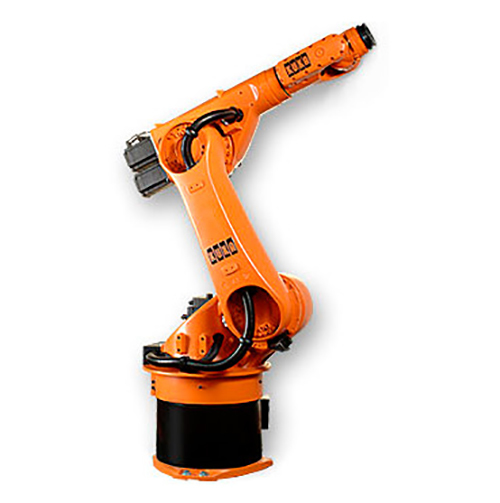    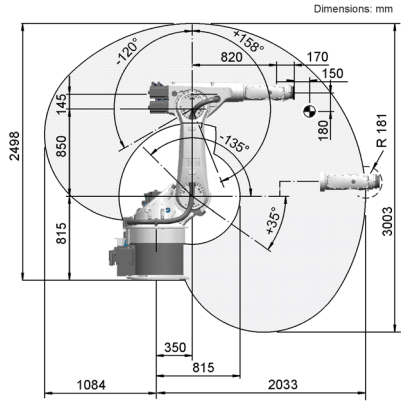

This manipulator is a 6-axis jointed-arm kinematic system, that consists of the following components:

- Base frame

- Rotating column

- Link arm

- Arm

- Triple-axis in-line wirst

All the joints are revolute, that means nor traslation or sliding linear motions between the bodies connected by this joint.

open('KukaKR6.wrl')

## Denavit-Hartenbergs parameters

Firstly, each link is assigned with a D-H coordinate frame, conform to the rules herebelow:

- The z-axis ($z_i$) is the rotation axis of each revolute joint.

- The x-axis ($x_i$) is the normal to the current z-axis ($z_i$) and the previous one ($z_{i-1}$) and must intersect the preious z-axis ($z_{i-1}$).

- The y-axis ($y_i$) is determined by the right-hand coordinate system.

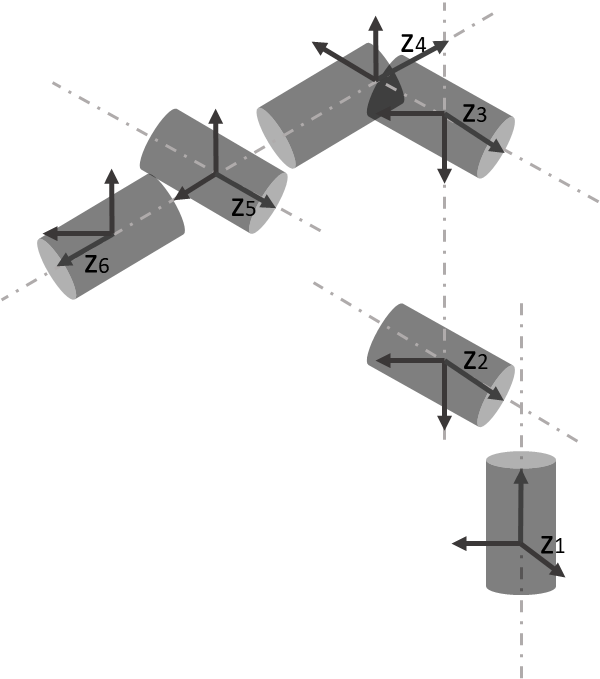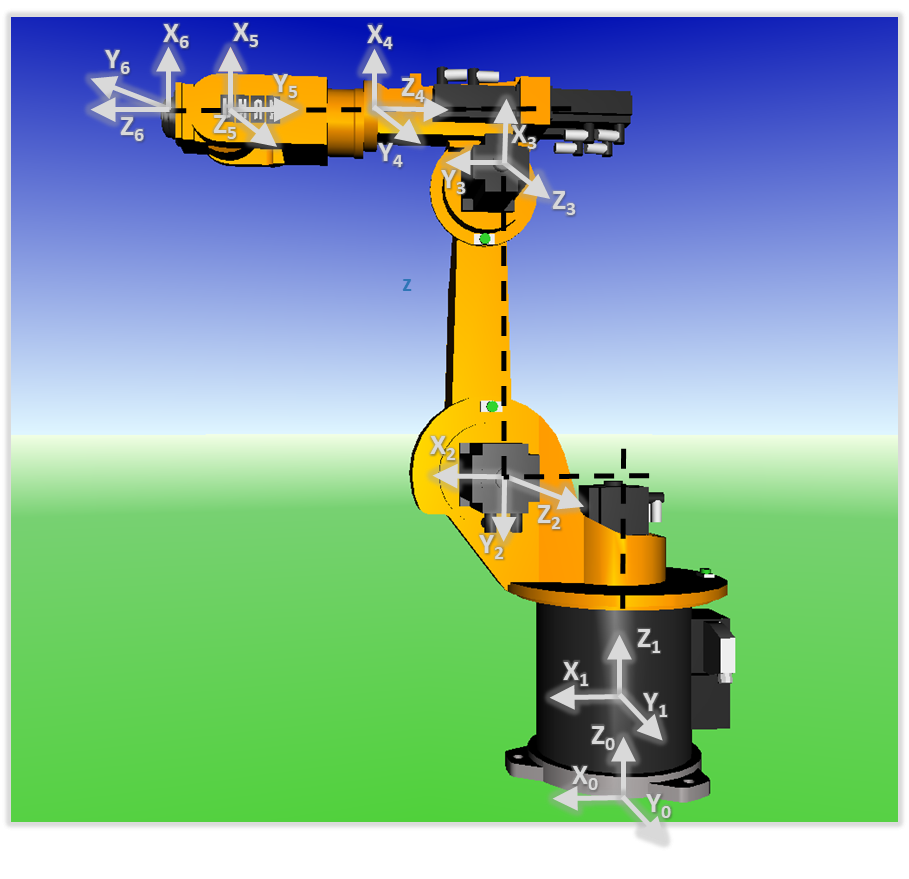

The Denavit-Hartenbergs parameters have been defined according to the DH convention, after having assigned a coordinate frame to each link of the Kuka KR 60. Hence, the D-H parameters can be computed as follow:

- $d_i$ is the distance from $x_{i-1}$ and $x_i$ along $z_i$

- $\theta_i$ (or offset) is the angle between $x_{i-1}$ and $x_i$ about $z_i$

- $a_i$ is the distance from $z_{i-1}$ to $z_i$ along $x_{i-1}$

- $a_i$ is the angle between $z_{i-1}$ to $z_i$ about $x_{i-1}$

dhParams = array2table([

     d       a      alpha     offset
    ____    ___    _______    ______

     675    350    -1.5708      0   
       0    850          0      0   
       0    145     1.5708      0   
    -820      0    -1.5708      0   
       0      0    -1.5708      0   
     170      0          0      0   



  675,  350, -pi/2, 0;
    0,  850,     0, 0;
    0,  145,  pi/2, 0;
 -820,    0, -pi/2, 0;
    0,    0, -pi/2, 0;
  170,    0,     0, 0], 'VariableNames', {'d', 'a', 'alpha', 'offset'});
disp(dhParams);
clear tableFormat;

## **Forward Kinematics**

The kinematics of the robot is solved using the Denavit-Hartenbergs' convention, which enables complete manipulation of the end-effector in three-dimensonal space.

The problem of the forward kinematics is to obtain the end-effector position with respect to a set of given joint angles $q_i$. The transformation from the current joint $i$ to the next is described by the matrix $A_{i+1}$:


$$A_{i+1} =\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\cos \left(\alpha_{i+1} \right) & \sin \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \cos \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)\cos \left(\alpha_{i+1} \right) & -\cos \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \sin \left(\theta \right)\\
0 & \sin \left(\alpha_{i+1} \right) & \cos \left(\alpha_{i+1} \right) & d_{i+1} \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The function `solve.forwardKinematics` solve this problem for a set of given joint angles `q`, by sequentially multipling each joint matrix $A_i$ ($T\;=A_1 A_2 A_3 A_4 A_5 A_6$), where $A_i$ is computed by `solver.computeT()`.

## **Inverse Kinematics**

Knowing the desired end-effector position, it is possible by meand of the inverse kinematics, to get the required joint angles to reach the target pose.

Though Newton-Raphson method is widely use to find the solution to the inverse kinematics, it doesn't guarantee the global convergence. Furthermore, also the equation solvability (target pose of end-effector and orientation) is not necessarily guardanteed. In 2009, a new technique based on the Levenberg-Marquardt was hence proposed [[1]](#M_1850E4CE). [[2]](#M_44DFAC54) used the Gauss-Newton with the Levenberg-Marquardt method as numerical optimization method, that, combined with an online learning approach, allows to reach the desired pose quicker on average. Though the online learning approach is to be considered out of the scope of this work, the numerical method is adopted.

Summarising, the Levenberg-Marquardt algorithm adaptively varies the parameter updates between the gradient descent update and the Gauss-Newton update:


$$\left(J^T \textrm{WJ}+\lambda \;I\right)h=J^T {\textrm{Wy}}_{\textrm{err}}$$


where $h$ is the parameter updated and $y_{\textrm{err}} =x_d -x\left(q\right)$

Hence: $h=\frac{J^T {\textrm{Wy}}_{\textrm{err}} }{J^T \textrm{WJ}+\lambda \;I}$.

After updating the solution $q_{\textrm{update}} =q+h^T$,  $\lambda \;$is updated:

- as the solution improves ($y_{\textrm{errNew}} <y_{\textrm{err}}$), $\lambda$ is decreased and q is updated ($q=q_{\textrm{update}}$): the Levenberg-Marquardt method approache the Gauss-Newton method, and the solutiont typically accelerated to the local minimum, as explained in [[3]](#M_48B7123D).

- if $y_{\textrm{errNew}} >y_{\textrm{err}}$, $\lambda$ is increased, and the solution diverges.

Please note, the weighting matrix is set to be simply an identity matrix.

The `solver.inverseKinematics()` implements this technique to find the desired configuration for the joint angles. The initial configuration `q` is the home configuration. A maximum number of iteration is provided to limit the computational cost at runtime: if no solution can be found in the range defined by the tolerance (default, ${10}^{-6}$), the last computed solution is returned. If the method doesn't converge to a solution, and all the calculated configurations have been rejected, the status is failed.

## **Inverse Dynamic**

Solving the inverse dynamic means calculate the joint forces and torques necessary to create the desired joint acceleration at the current joint position and velocities.

The Newton-Euler method allows to describe the dynamic motion of a rigid body system, in terms of forces and torques. In contrast with the Euler-Lagrange method (energy based) that considers the system as a whole, the NE makes use of one equation for each link, that is vualuated in a numeric form and reursive way. In particular:


$$\begin{array}{l}
\textrm{Newton}\to \;\sum_i f_i =\frac{d}{\textrm{dt}}\left({\textrm{mv}}_c \right)\\
\textrm{Euler}\to \sum_i \mu_i =\frac{d}{\textrm{dt}}\left(I\omega \right)=I\dot{\omega} +\omega \times I\omega 
\end{array}$$


The algorithm can be splitted in two steps: *forward iteration* and *backward iteration *[[4]](#M_0F3EC533). 

**The forward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the base to the end-effector):

- Calculate $\omega_i \;$as sum of $\omega_{i-1}$(expredsed in frame $i$) and a term due to $\dot{\theta_i }$:$\omega_i =R\left(\omega_{i-1} +z_0 \theta_i \right)$

- Calculate $\dot{\omega_i } \;$as sum of ${\dot{\omega} }_{i-1}$(expressed in frame $i$) and a term due to $\ddot{\theta_i } \;$and the velocity product term due to $\omega_i$and $\dot{\theta_i }$: ${\dot{\omega \;} }_i =R\left({\dot{\omega \;} }_{i-1} +z_0 \dot{\theta_i } \;+\omega_{i-1} \times z_0 \dot{\theta_i } \;\right)$

- Calculate $\ddot{\theta_i } \;$ as sum of a term due to ${\dot{\omega} }_i$ and a term due to $\omega_i$:$\ddot{\theta_i } \;={\dot{\omega \;} }_i \times p^* +\omega_i \times \omega_i \times p^* +R\;G$

**The backward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the end-effector to the base):

- Calculate $F_i$ as sum of $F_{i+1}$ and the external forces. $F_i =M_j \left(\dot{\omega_j } \times r+\omega_j \times \omega_j \times r+{\dot{\theta} }_j \right)+\;\sum_{j=i+1}^n f_j$

- Calculate $\tau_i$ as the component of $F_i$ along the joint skew axis: $\tau_j =I\dot{\omega_j } +\omega_j \times I\omega_j$ [[5]](#M_BCC0813E)

For more details about the algorithms, please refer to its implementation in `solver.inverseDynamics()`.

## Trajectory Planning

The trajectory planning problem consists in find a time series of successive joint angles that allows to achieve a task, a target configuration. 

### **Comparison between task space and joint space**

Joint-space description: the description of the motion to be made by the robot by its joint values. The motion between the two points is unpredictable.

Operational-space description: the description of the motion is in the operational space (cartesian or working space). The motion between two points is known and controllable at all time, but it is difficult to ensure that singuarities does not occur.

**Task space**

- Calculate the path from the initial point to the final point

- Assing a total time $T_{\textrm{path}}$to traverse the path

- Discretize the points in time and space

- Blend a continuous time function between these points

- Solve inverse kinematics at each step

**Joint space**

- Calculate the inverse kinematic solution from the initial point to the final point

- Assign the total time $T_{\textrm{path}}$using maximal velocities in joints

- Discretize the individual joint trajectories in time

- Blend a continuous function between these point

A small summary of the pro (OK) and contra (NO) of each space trajectory is herebelow described.


$$\matrix{
\textbf{Operational Space Trajectory} & \textbf{Joint Space Trajectory}                               \cr
\text{OK: Motion is predictable} & \text{NO: Motion not predictable} \cr
\text{OK: Collision-free path obtainable}    & \text{NO: Collision-free path not guaranteed}                             \cr
\text{NO: IK computed each time step}        & \text{OK: IK computed only once}                                     \cr
\text{NO: Unknown how to set total time}    & \text{OK: Joint and velocity constraints} \cr
\text{NO: Actuator motion not always smooth} & \text{OK: Actuator motion smooth} \cr
}$$


### Polynomial trajectory

In order to generate the trajectory, to move from the initial configuration to the target configuration, the path between the two waypoints shall be defined.

**Cubic Polynomial**

For each joint a function is required: its initial value at $t_0$ coincides with the initial configuration, while the final value at $t_F$ is the desired goal position. The four constraints used in the polynomial definition are $\theta \left(0\right)=\theta_0 ;\;\theta \left(t_F \right)=\theta_f ;\dot{\theta} \left(0\right)=0;\dot{\theta} \left(t_F \right)=0$. Hence:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 \\
\ddot{\theta} \left(t\right)=a_2 +{6a}_3 t
\end{array}$$


syms q0 qf v0 vf t;
c = [q0; v0; 0; 0];
T0 = [1 t; 0 1];
invTF = [3/t^2, -1/t;
    -2/t^3,  1/t^2];
c(3:4) = invTF * ([qf; vf] - T0*c(1:2));
disp(c);

Please, refer to the function `trajectory.cubicPolynomial `[[here](matlab:open('./srcs\matlab\+trajectory\cubicPolynomial.m'))] for the implementation.

**Quintic Polynomial**

To consider position, velocity and acceleration at the beginning and end of a path segment, a quintic polynomial is required:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 +a_4 t^4 +a_5 t^5 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 +{4a}_4 t^3 +5a_5 t^4 \\
\ddot{\theta} \left(t\right)={2a}_2 +{6a}_3 t+12a_4 t^2 +20a_5 t^3 
\end{array}$$


syms q0 qf v0 vf a0 af t;
c = [q0; v0; a0; 0; 0; 0];
T0 = [1 t t^2; 0 1 2*t; 0 0 2];
invTF = [10/t^3, -4/t^2,  1/(2*t);
    -15/t^4,  7/t^3, -1/t^2;
    6/t^5, -3/t^4,  1/(2*t^3)];

|    Startup KukaKR6...    |
-> Reloading D-H parameters...
-> Reloading Dynamic parameters...
Mass: 
    5.0000
    5.0000
    5.0000
    4.0885
    1.6154
    0.0160

-> Reloading Bus Objects...
-> Setting Variant Subsystem...
TP_MODE=1->["TaskSpace"]
-> Reloading Waypoints...
Computing home configuration...
-> Loading model "KukaSimModel.slx"...
Initialization Done.


c(4:6) = invTF * ([qf; vf; af] - T0*c(1:3));
disp(c);

Please, refer to the function `trajectory.quinticPolynomial()` [[here](matlab:open('./srcs\matlab\+trajectory\quinticPolynomial.m'))] for the implementation.

## **lib_Solver **

The library `lib_Solver` implements the system blocks, that call the respective function described above.

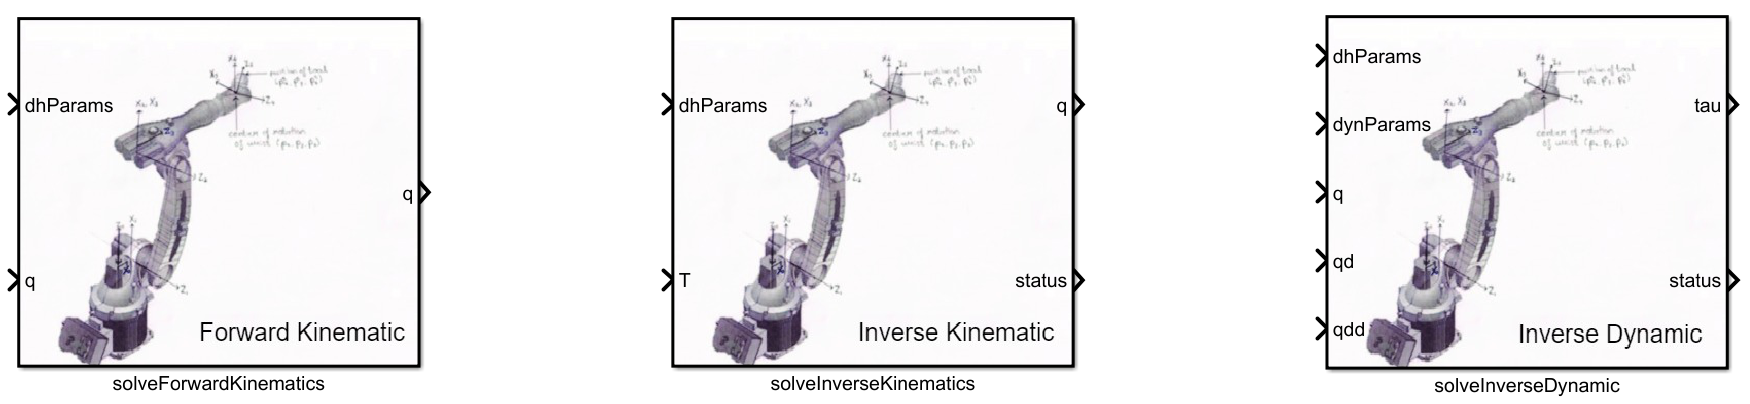

#### solveForwardKinematics lib

The `solveForwardKinematics` system block gets in input the DH parameters of the system and the joint configuration $q_{\left\lbrack 1\textrm{x6}\right\rbrack }$, and outputs the link positions.

#### solveInverseKinematics lib

The `solveInverseKinematics` system block computes, by means of DH parameters and the desired end-effector position in the form of the homogeneous transformation $T_{\left\lbrack 4\textrm{x4}\right\rbrack }$, the required joint angles $q_{\left\lbrack 1\textrm{x6}\right\rbrack }$.

#### solveInverseDynamic lib

The `solveInverseDynamic` system block is responsible for calculating the torque required for the specific joint configuration. Following input parameters are required:

- DH parameters

- Dynamic parameters (Inertia matrix, Mass, External Forces)

- joint angles

- joint velocities

- joint accelerations

## **TrajectoryGenerator System Object**

The Matlab System Object `core.trajectoryGenerator` [[here](matlab:open('./srcs\matlab\+core\TrajectoryGenerator.m'))] implements specific methods and properties for modeling the trajectory generation algorithm. By means of a cubic or a quintic polynomial, the path that connects pre-defined waypoints is computed. 

The System Object implements a custom mask that allow the user to easily configure the desired trajectory:

- SolverSpace: whether `TaskSpace` or `JointSpace`. For the joint space the orientations, if defined, are automatically integrated.

- Method: whether `Cubic` or `Quintic Polynomial`. If quintic is selected, the popup allow the user to select the desired acceleration, otherwise is hidden.

- Waypoints: the set of waypoints.

- TimePoints: the set of time points associated to the waypoints.

- Velocity: the desired velocities, associated to the waypoints.

- Acceleration: the desired acceleration, associated to the waypoints (available only for quintic polynomial).

- (Experimental - still wip) Integrate orientations using SLERP.

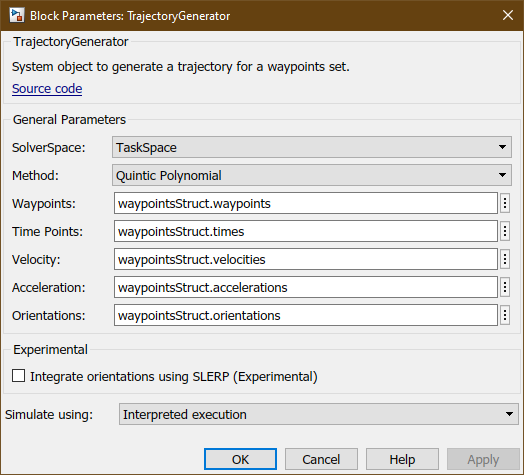

## KukaSimModel

The model "*KukaSimModel"* simulates the motion planning of the Kuka KR, described by the DH parameters and dynamic parameters loaded in the workspace.  The robot will follow the trajectory generated at run time for the set of waypoints present in the workspace.

open_system('KukaSimModel.slx');

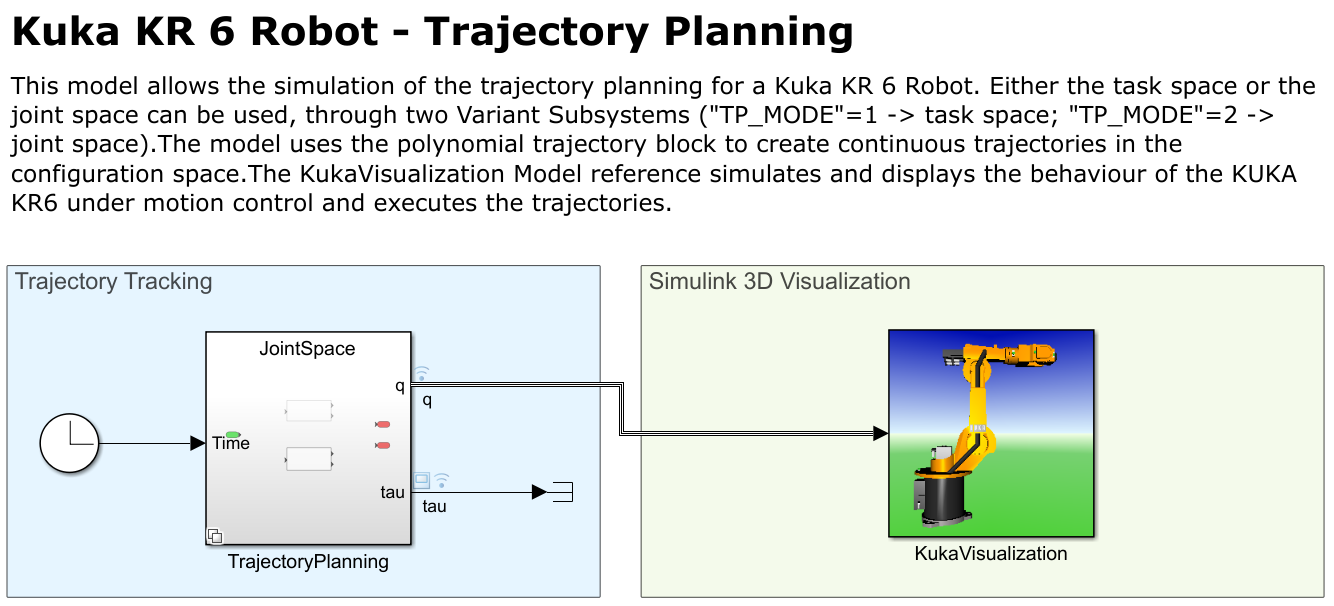

The model can be splitted, architecturally speaking, into two parts: the "*TrajectoryPlanning*" and the *"KukaVisualization"* subsystem. While the former is responsible for the proper motion planning, the latter displays the movement of the KUKA KR 60 by means of the Simulation 3D Animation toolbox. 

### TrajectoryPlanning

The "*TrajectoryPlanning"* subsystem is a Variant Subsystem, that enables whether the "*TaskSpace*" or the "*JointSpace*" subsystem, basing on the value that the variable `TP_MODE` is assigned.

- `TP_MODE = 1 `for the simulation in the Task Space;

- `TP_MODE = 2 `for the simulation in the Joint Space.

#### TaskSpace Subsystem

#### 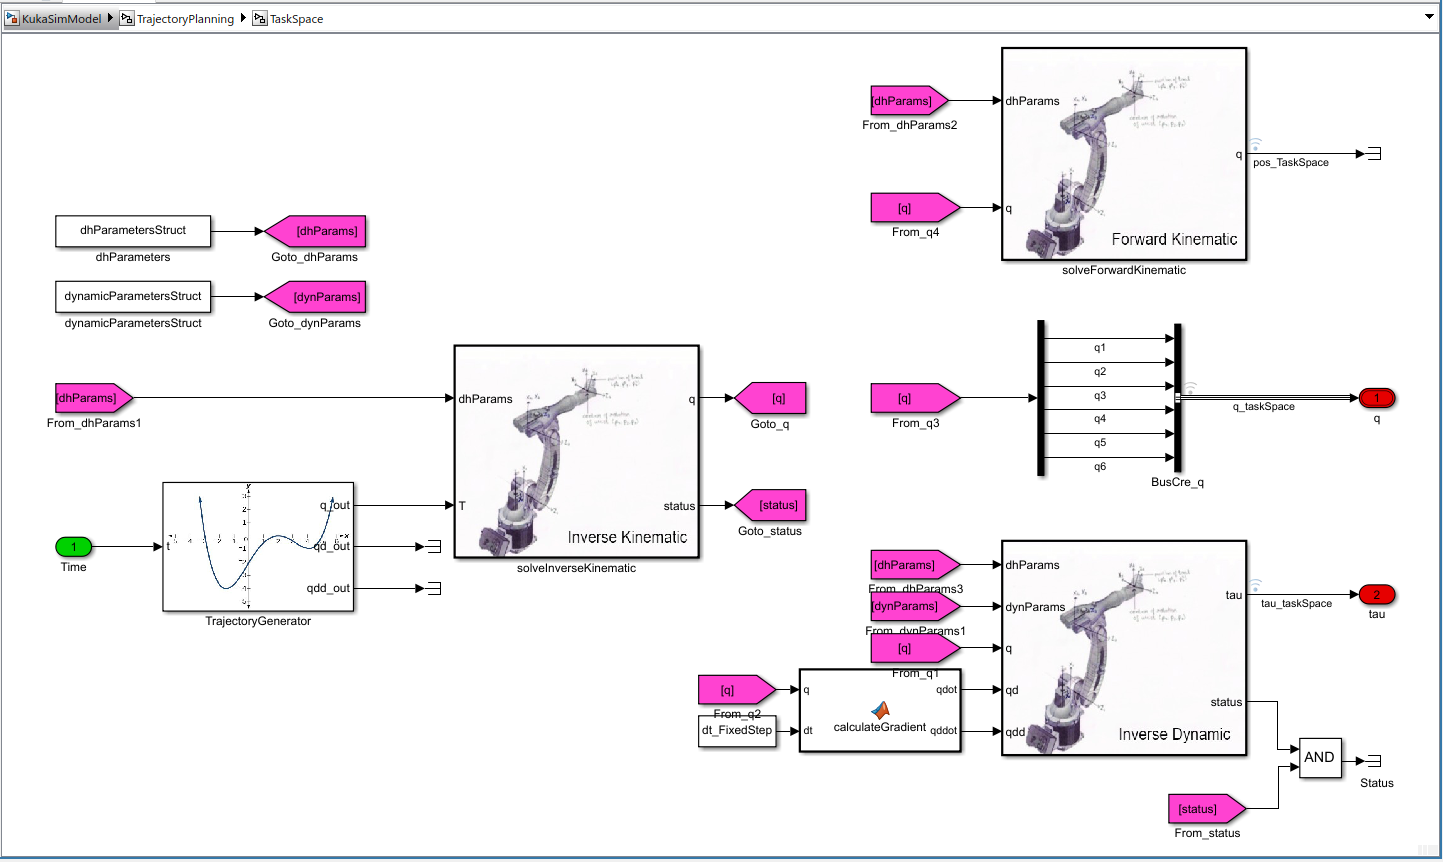

When the TaskSpace is chosen, the main steps executed are:

- Calculate the Trajectory basing on the waypoints selected and its method (cubic or polynomial).

- The required position at the specific time step is returned and passed through the `solveInverseKinematics`, in the form of homogeoneous transform T.

- The `solveInverseKinematics` library calcultes than the required joint angles position to let the end-effector reach the desired position.

- The joint angles `q` are hence passed to the inverse dynamic block that calculates the necessary torques $\tau_{\left\lbrack 6\textrm{x1}\right\rbrack }$. In order to calculate the joint velocities and the joint acceleration, the gradient of the position and the velocities are respectively calculated.

- The joint angles q are hence passed to the forward kinematic in order to calculate the real position of the links. The variable `pos_TaskSpace` can be then plotted in order to check and verify the real movement of the robot.

- The joint angles q are hence propagated in form of a bus object `BusCre_q`, using a demux to pass the each vector element with the proper name to the bus`.`

#### **JointSpace Subsystem**

### 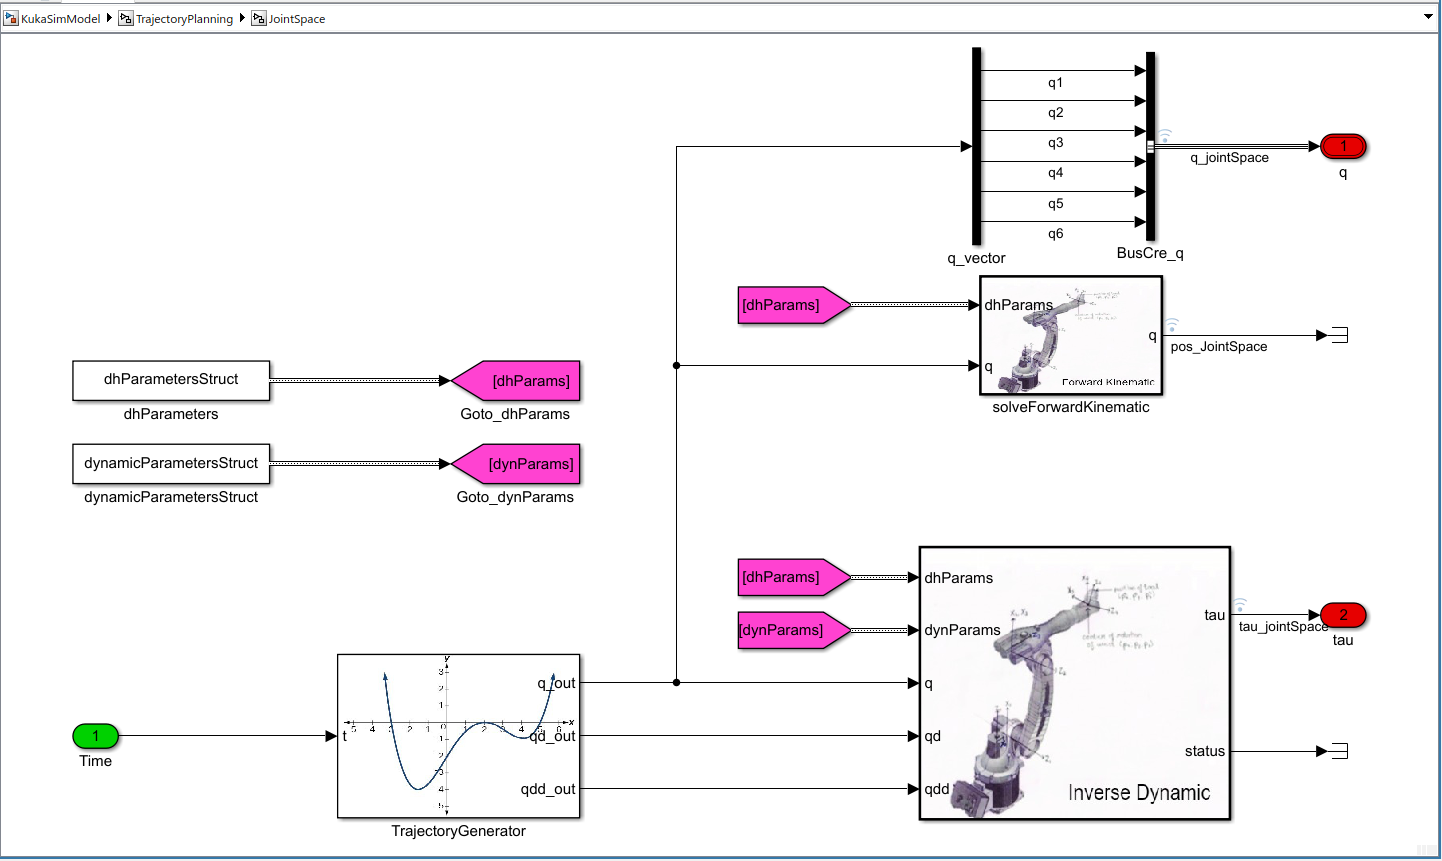

The Trajectory Generation when the JointSpace is selected, require the InverseKinematics to be calculated before the TrajectoryGenerator is executed.

This means:

-  An *InitFcn* callback is configured to run the Inverse Kinematics on the waypoints

- The result `jointWaypoints `is fed into the TrajectoryGenerator object, that calculates the required joint position at the specific time step, in order to follow the defined path. 

- The calculated joint angles, as well as the velocities and the accelerations are passed to the Inverse Dynamic block for the torque computation.

- The calculated joint angles are hence passed to the forward kinematic in order to calculate the real position of the links. The variable `pos_JointSpace` can be then plotted in order to check and verify the real movement of the robot.

- The joint angles q are hence propagated in form of a bus object `BusCre_q`, using a demux to pass the each vector element with the proper name to the bus`.`

### KukaVisualization Subsystem

The KukaVisualization Subsystem sets the calculated joint angles, for the wrl visualisation, using the Simulink 3D Animation toolbox.

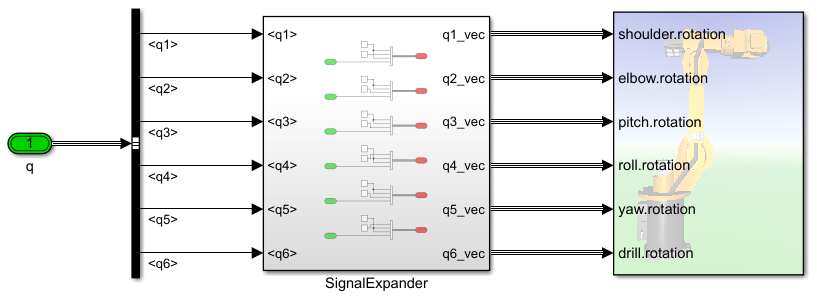

The inport q is a specific bus `Bus_q `defined in the workspace:

| Start simulation for "TaskSpace"...  |
[26-Sep-2021 23:37:39]: Setting Variant Subsystem TP_MODE=1...
[26-Sep-2021 23:37:39]: Setting "StopTime"=30s...
[26-Sep-2021 23:37:39]: Setting "FastRestart"="off"... -> Compilation enabled:
[26-Sep-2021 23:37:39]: Setting TrajectoryGenerator "PolynomialMethod"="Cubic Polynomial"...
* Current polynomial differs from previous simulation ["Cubic Polynomial"~="Quintic Polynomial"].
[26-Sep-2021 23:37:39]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[26-Sep-2021 23:37:40]: Start simulation...
[26-Sep-2021 23:37:40]: Run simulation...
[26-Sep-2021 23:37:45]: Stop simulation.
[26-Sep-2021 23:37:45]: Plot

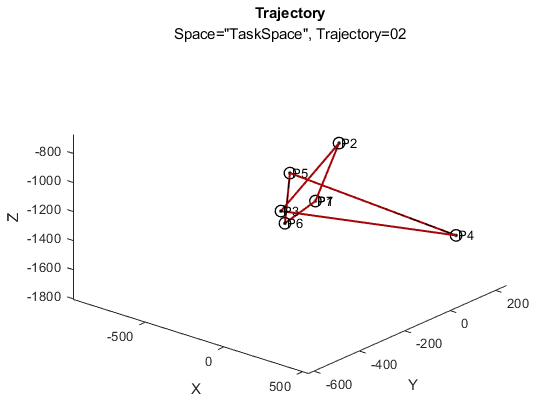

if exist("IsSixAxesRobotInitialized", 'var')
    disp('Bus_q:'); disp(Bus_q);
    disp('Bus_q.Elements(1):'); disp(Bus_q.Elements(1));
end

The *SignalExpander* creates a vector for each joint angle, that defines in which axes shall the rotation take place.

## **Simulation**

The simulation needs a specific environment to be setup. Following steps are hence necessary:

- Add Matlab paths where sources are inside

- Load DH parameters

- Load Dynamic parameters

- Load BusObjects

- Load Waypoints

- Set Variant Subsystem

- Load simulation model.

In the following section the user can define some configuration to run the simulation:

- `Model` name ("KukaSimModel" as default);

- `Space`: whether TaskSpace or JointSpace;

- `Trajectory`: the gen_waypointSet script to run for the generation of the waypointStruct;

- `Polynomial`: whether quintic or cubic polynomial;

- `Visualize`: whether the wrl model shall be opened.

### **Run setup**

% Set configuration
colors.red    = [.64 .02 .03];

[26-Sep-2021 23:37:46]: TaskSpace simulation Done!


colors.blue   = [.02 .52 .51];

| Start simulation for "JointSpace"...  |
[26-Sep-2021 23:37:52]: Setting Variant Subsystem TP_MODE=2...
[26-Sep-2021 23:37:52]: Setting "StopTime"=30s...
[26-Sep-2021 23:37:52]: Setting "FastRestart"="off"... -> Compilation enabled:
* Current space differs from previous simulation ["JointSpace"~="TaskSpace"].
[26-Sep-2021 23:37:52]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[26-Sep-2021 23:37:52]: Start simulation...
[26-Sep-2021 23:37:52]: Solve Inverse Kinematics in JointSpace...
[26-Sep-2021 23:37:58]: Run simulation...
[26-Sep-2021 23:38:00]: Stop simulation.
[26-Sep-2021 23:38:00]: Plotting waypoints and trajectory...


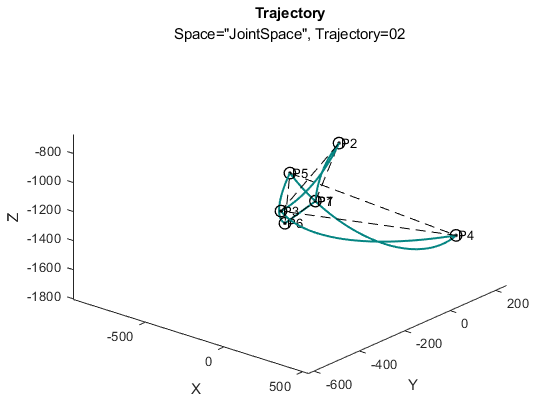

colors.green  = [.04 .79 .17];

clear config; % ensure clear config
config.modelName    = 'KukaSimModel';
config.space        = enum.SpaceEnum.TaskSpace;
config.trajectory   = 5;
config.polynomial   = "Quintic Polynomial";

config.visualize    = false;


[26-Sep-2021 23:38:01]: JointSpace simulation Done!


% Startup setup

| Start simulation for "JointSpace"...  |
[26-Sep-2021 23:38:01]: Setting Variant Subsystem TP_MODE=2...
[26-Sep-2021 23:38:01]: Setting "StopTime"=30s...
[26-Sep-2021 23:38:01]: Setting "FastRestart"="off"... -> Compilation enabled:
[26-Sep-2021 23:38:01]: Setting TrajectoryGenerator "PolynomialMethod"="Quintic Polynomial"...
* Current polynomial differs from previous simulation ["Quintic Polynomial"~="Cubic Polynomial"].
[26-Sep-2021 23:38:01]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[26-Sep-2021 23:38:01]: Start simulation...
[26-Sep-2021 23:38:01]: Solve Inverse Kinematics in JointSpace...
[26-Sep-2021 23:38:07]: Run simulation...


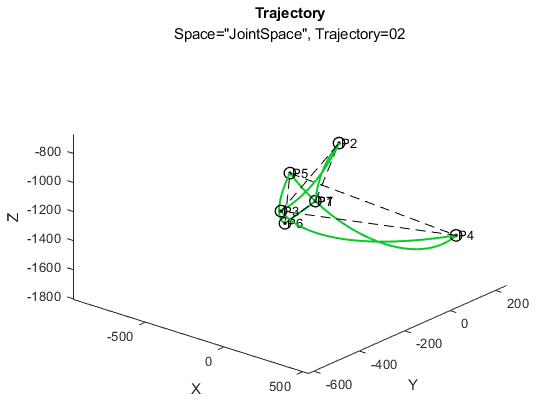

startup;
config.homeConfig   = eeHomeConfig;

% initialize lastRun variable
lastRun = struct( ...
    'polynomial', [], ...

    'space', [], ...
    'trajectory', [], ...

[26-Sep-2021 23:38:09]: JointSpace simulation Done!


    'waypoints', []);

### **Simulate TaskSpace - gen_02**

In order to trigger the simulation only few steps are still necessary: set the space and the call the `runSimulation` function.

config.trajectory   = 2;
config.space        = enum.SpaceEnum.TaskSpace;
config.plotColor    = colors.red;
[simOutTS, lastRun] = runSimulation(config, lastRun);

printlog('%s simulation Done!', char(config.space));
disp('========================================');

### **Simulate JointSpace [Cubic] - gen_02**

In order to trigger the simulation only few steps are still necessary: set the space and the call the `runSimulation` function.

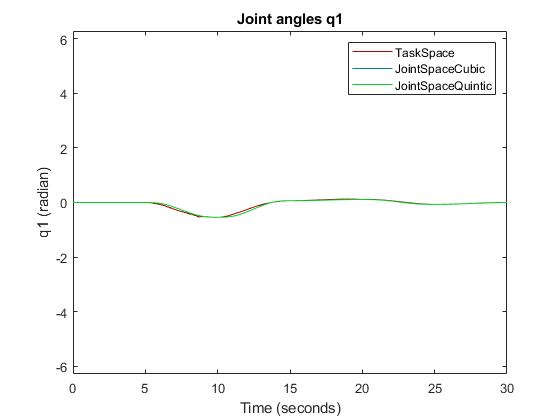

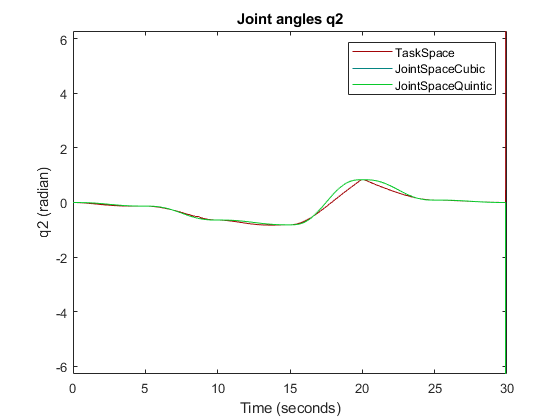

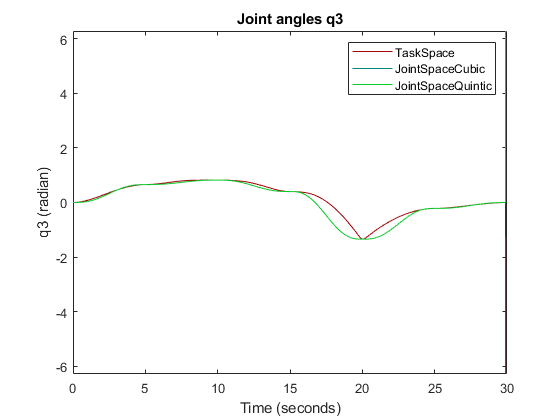

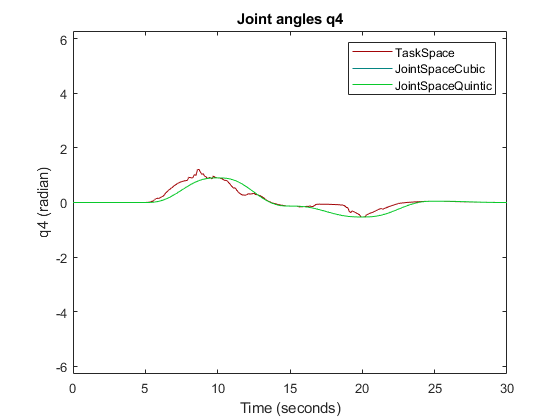

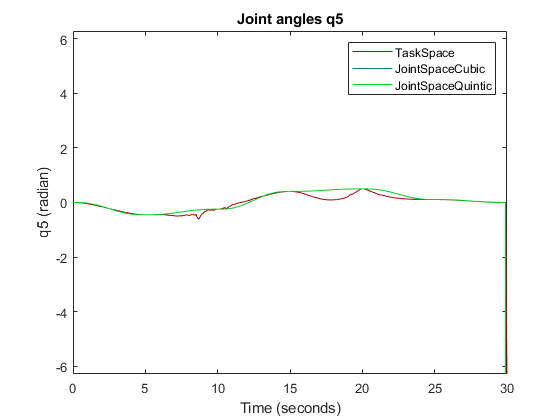

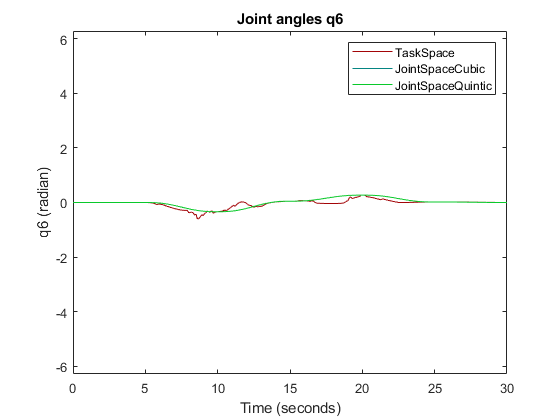

config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.blue;
config.polynomial   = "Cubic Polynomial";
[simOutJSC, lastRun] = runSimulation(config, lastRun);

printlog('%s simulation Done!', char(config.space));
disp('========================================');

### **Simulate JointSpace [Quintic] - gen_02**

In order to trigger the simulation only few steps are still necessary: set the space and the call the `runSimulation` function.

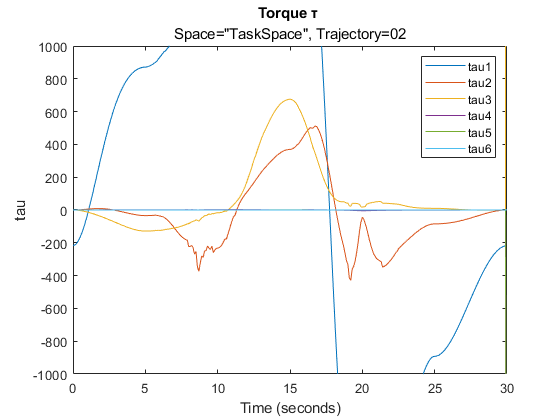

config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.green;

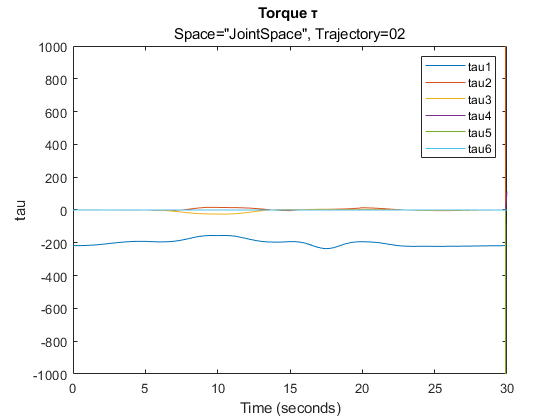

config.polynomial   = "Quintic Polynomial";
[simOutJSQ, lastRun] = runSimulation(config, lastRun);


printlog('%s simulation Done!', char(config.space));
disp('=================================================');

### Compare joint angles trajectories** - gen_02**

| Start simulation for "JointSpace"...  |
[26-Sep-2021 23:38:57]: Setting Variant Subsystem TP_MODE=2...
[26-Sep-2021 23:38:57]: Setting "StopTime"=35s...
[26-Sep-2021 23:38:58]: Setting "FastRestart"="off"... -> Compilation enabled:
* Current trajectory differs from previous simulation ["5"~="2"].
* Current waypoints differs from previous simulation.
[26-Sep-2021 23:38:58]: Generating waypoints "gen_waypointSet_05"...
Waypoint set:
        1345        1295        1045        1145        1145        1045        1295        1345
           0       -1200        -750        -100         100         750        1200           0
        -315          85         485        -415        -415         485          85        -315

[26-Sep-2021 23:38:58]: Start simulation...
[26-Sep-2021 23:38:58]: Solve Inverse Kinematics in JointSpace...
[26-Sep-2021 23:39:01]: Run simulation...
[26-Sep-2021 23:39:03]: Stop simulati

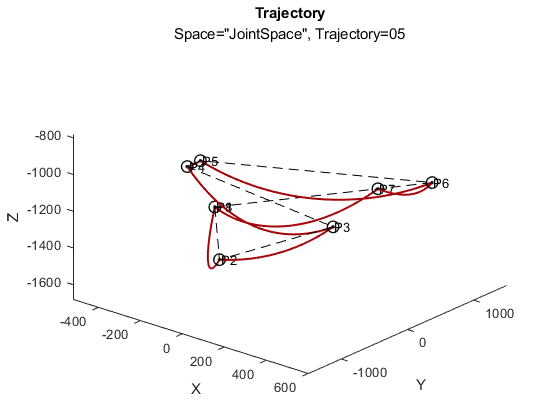

singlePlot = false;
verticalAlignment = false;

qT  = simOutTS.logsout.getElement('q').Values;
qJC = simOutJSC.logsout.getElement('q').Values;

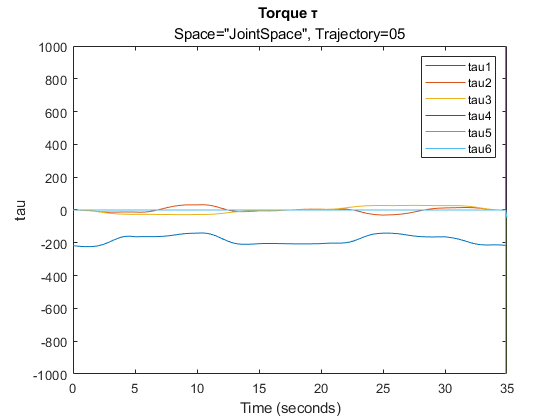

qJQ = simOutJSQ.logsout.getElement('q').Values;
joints = fieldnames(qT);


if singlePlot
    figure; hold on;
end
for i=1:numel(joints)
    if ~singlePlot
        figure;
    elseif verticalAlignment
        subplot(6, 1, i);
    else
        subplot(3, 2, i);
    end
    plot(qT.(joints{i}), "Color", colors.red); hold on;
    plot(qJC.(joints{i}), "Color", colors.blue);
    plot(qJQ.(joints{i}), "Color", colors.green);
    ylim([-2*pi, 2*pi]);
    legend(char(enum.SpaceEnum.TaskSpace), ...
        sprintf('%s%s', char(enum.SpaceEnum.JointSpace), 'Cubic'), ...
        sprintf('%s%s', char(enum.SpaceEnum.JointSpace), 'Quintic'));
    title(sprintf('Joint angles %s', joints{i}));
end


The joint space trajectory in red is generally smoothier than the blue one, which is task-based. In the plot of the joint "q4" and "q5" the slope of the curves can be noticed: the slope for the trajectory in the task space is pretty higher (that means more actuator motion in general) than the one joint-based.

### Compare torques** - gen_02**

% plot torques
figure;
plotTorque(char(enum.SpaceEnum.TaskSpace), config.trajectory, simOutTS.logsout.getElement('tau').Values);
figure;
plotTorque(char(enum.SpaceEnum.JointSpace), config.trajectory, simOutJSQ.logsout.getElement('tau').Values);

### Run task in Joint Space - gen_05

% configure
config.trajectory   = 5;
config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.red;
% run the simulation
[simOutJS05, lastRun] = runSimulation(config, lastRun);
% plot the torque
figure;
plotTorque(char(enum.SpaceEnum.JointSpace), config.trajectory, simOutJS05.logsout.getElement('tau').Values);

function [simOut, lastRun] = runSimulation(config, lastRun)
disp('========================================');
fprintf('| Start simulation for "%s"...  |\n', config.space.char());
disp('========================================');
assignin("base", 'TP_MODE', double(config.space))
printlog('Setting Variant Subsystem TP_MODE=%d...', double(config.space));

if config.visualize
    open('KukaKR6__.wrl');
end

% start simulation
[~, waypointsStruct] = enableFastRestartIfPossible(config.modelName, lastRun, config);
printlog('Generating waypoints "gen_waypointSet_%02d"...', config.trajectory);
assignin("base", 'waypointsStruct', waypointsStruct);
disp('Waypoint set:'); disp(waypointsStruct.waypoints);

warning('off', 'MATLAB:system:saveObjectImplNotImplemented');
simOut = sim(config.modelName);

% get trajectory information
varName = sprintf('pos_%s', char(config.space));
simOutTrajectory = reshape(simOut.logsout.getElement(varName).Values.Data(:, 6, 1:end-1), ...
    3, numel(simOut.tout)-1);
% plot trajectory
printlog('Plotting waypoints and trajectory...');
figure; hold on;
plotWaypoints(waypointsStruct.waypoints, simOutTrajectory, config.plotColor);
title('Trajectory', sprintf('Space="%s", Trajectory=%02d', char(config.space), config.trajectory));
view(40, 35);

% save information of current simulation
lastRun = struct( ...
    'polynomial', config.polynomial, ...
    'space', config.space, ...
    'trajectory', config.trajectory, ...
    'waypoints', waypointsStruct);
end

function plotTorque(spaceName, trajectory, simOutTorques)
    plot(simOutTorques);
    legend('tau1', 'tau2', 'tau3', 'tau4', 'tau5', 'tau6');
    ylim([-1000, 1000]);
    title('Torque τ ', sprintf('Space="%s", Trajectory=%02d', char(spaceName), trajectory));
end

## Bibliography

[1] T. Sugihara, "Solvability-unconcerned inverse kinematics based on Levenberg-Marquardt method with robust damping," *2009 9th IEEE-RAS International Conference on Humanoid Robots*, 2009, pp. 555-560, doi: 10.1109/ICHR.2009.5379515.

[2] K. Ofjall and M. Felsberg,  "Rapid explorative direct inverse kinematics learning of relevant locations for active vision," in *2013 IEEE Workshop on Robot Vision (WORV 2013)*, Clearwater Beach, FL, 2013 pp. 14-19. doi: 10.1109/WORV.2013.6521932

[3] [https://people.duke.edu/~hpgavin/ce281/lm.pdf](https://people.duke.edu/~hpgavin/ce281/lm.pdf)

[4] [https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/](https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/)

[5] Roy, F., "Inverse Dynamics - The Recursive Newton-Euler Method.", Springer US, 1987, pp. 65-77, doi: 10.1007/978-0-387-74315-8_4